# Spatial transformations

## Modeling and Control of Robotic Manipulators

## Inverse Kinematics

#### 1. Import UR 10

Import the UR10 rigid body object *ur10* from the file *'ur10.urdf'*. Investigate the link and joint structure with `showdetails`.

ur10 = importrobot('ur10.urdf');
ur10.showdetails()

--------------------
Robot: (8 bodies)

 Idx             Body Name                 Joint Name                 Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                 ----------                 ----------             ----------------   ----------------
   1             base_link                world_joint                      fixed                     world(0)   shoulder_link(2)  
   2         shoulder_link         shoulder_pan_joint                   revolute                 base_link(1)   upper_arm_link(3)  
   3        upper_arm_link        shoulder_lift_joint                   revolute             shoulder_link(2)   forearm_link(4)  
   4          forearm_link                elbow_joint                   revolute            upper_arm_link(3)   wrist_1_link(5)  
   5          wrist_1_link              wrist_1_joint                   revolute              forearm_link(4)   wrist_2_link(6)  
   6          wrist_2_link              wrist_2_j

#### 2. Generate an inverse kinematics solver object

Generate an inverse kinematics solver object *ikur10* for the rigid body tree object *ur10*.

ikur10 = robotics.InverseKinematics('RigidBodyTree', ur10);

#### 3. Define a target pose

Define a target pose in terms of a transform *targetposeur10* that results from a translation $$[d_x \ d_y \ d_z]^T =[0.8 \ 0 \ 1.4]^T$$ and a rotation with Euler angles$$[\phi \ \theta \ \psi]^T=[\pi/4  \ \pi/4  \ -\pi/4]^T$$.

trans_vec1 = [0.8 0 1.4];
eul_angles1 = [pi/4 pi/4 -pi/4];
t1_1 = trvec2tform(trans_vec1);
t2_1 = eul2tform(eul_angles1);
targetposeur10 = t1_1*t2_1

targetposeur10 =     0.5000   -0.8536   -0.1464    0.8000
    0.5000    0.1464    0.8536         0
   -0.7071   -0.5000    0.5000    1.4000
         0         0         0    1.0000


#### 4. Determine the inverse kinematics solution

Determine the inverse kinematics solution *configur10* with the method *ikur10* for the target pose of the end effector link frame *'ee_link'* with a unit error weight vec,tor $$w=[1 \ 1 \ 1 \ 1 \ 1 \ 1]$$. 

weights = ones(1,6);
initialconfigur10 = ur10.homeConfiguration;
[configur10, solnInfo10] = ikur10('ee_link', targetposeur10, weights, initialconfigur10);
figure(1);
hold on;
ur10.show(configur10);
hold off;

#### 5. Calculate the pose error

Calculate the pose (task space) error $$\mathbf{e}(\mathbf{q})$$ according to equations (1) and (2) between *targetposeur10* and the end effector transform of the resulting joint configuration *configur10*.

isposeur10 = ur10.getTransform(configur10, 'ee_link');
poseerror_ikur10 = robotics.manip.internal.IKHelpers.poseError(targetposeur10, isposeur10);
disp('UR10 Robot');

UR10 Robot


disp(['Robotics System Toolbox norm(e) :  ', num2str(norm(poseerror_ikur10))]);

Robotics System Toolbox norm(e) :  7.3235e-08


#### 6. Import Sawyer rigid body tree

Import the Sawyer rigid body tree *sawyer* from the file *'sawyer.urdf'*. Inspect the *RigidBodyTree* structure of the Sawyer robot.

sawyer = importrobot('sawyer.urdf');
sawyer.showdetails()

--------------------
Robot: (20 bodies)

 Idx                  Body Name                  Joint Name                  Joint Type                  Parent Name(Idx)   Children Name(s)
 ---                  ---------                  ----------                  ----------                  ----------------   ----------------
   1             controller_box        controller_box_fixed                       fixed                           base(0)   
   2              pedestal_feet         pedestal_feet_fixed                       fixed                           base(0)   
   3                   pedestal              pedestal_fixed                       fixed                           base(0)   
   4        right_arm_base_link             right_arm_mount                       fixed                           base(0)   right_l0(5)  
   5                   right_l0                    right_j0                    revolute            right_arm_base_link(4)   head(6)  right_l1(9)  right_torso_itb(19

#### 7. Remove bodies and joints in the rigid body tree

For sake of clarity Remove those bodies and joints in the *RigidBodyTree* that are non-relevant for the Sawyer arm kinematics and visualize the robot with `show`.

% delete headpan joint
sawyer.removeBody('head');
sawyer.removeBody('right_arm_itb');
sawyer.removeBody('right_hand_camera');
sawyer.removeBody('torso');
sawyer.removeBody('right_torso_itb');
sawyer.showdetails()

--------------------
Robot: (13 bodies)

 Idx                  Body Name                  Joint Name                  Joint Type                  Parent Name(Idx)   Children Name(s)
 ---                  ---------                  ----------                  ----------                  ----------------   ----------------
   1             controller_box        controller_box_fixed                       fixed                           base(0)   
   2              pedestal_feet         pedestal_feet_fixed                       fixed                           base(0)   
   3                   pedestal              pedestal_fixed                       fixed                           base(0)   
   4        right_arm_base_link             right_arm_mount                       fixed                           base(0)   right_l0(5)  
   5                   right_l0                    right_j0                    revolute            right_arm_base_link(4)   right_l1(6)  
   6                   rig

#### 8. Calculate the inverse kinematics solution

Following the same steps as in case of the UR10 robot calculate the inverse kinematics solution for the Sawyer robot for a target pose *targetposesawyer*$$[d_x \ d_y \ d_z] =[0.6 \ 0.0 \ 0.6]$$ and target orientation $$[\phi \ \theta \ \psi]=[\pi/4  \ \pi/6  \ -\pi/4]$.$

transvec_2 = [0.6 0 0.6]; 
eul_angles2 = [pi/4 pi/6 -pi/4];
t1_2 = trvec2tform(transvec_2);
t2_2 = eul2tform(eul_angles2);
targetposesawyer = t1_2*t2_2;

iksawyer = inverseKinematics('RigidBodyTree', sawyer);
initialconfigsawyer = sawyer.homeConfiguration;

[configsawyer, solnInfo_sawyer] = iksawyer('right_hand', targetposesawyer, weights, initialconfigsawyer);


#### 9. Calculate the pose error

Calculate the pose (task space) error $$\mathbf{e}(\mathbf{q})$$ according to equations (1) and (2) between *targetposesawyer* and the end effector transform of the resulting joint configuration *configsawyer*.

isposesawyer = sawyer.getTransform(configsawyer, 'right_hand');
poseerror_iksawyer = robotics.manip.internal.IKHelpers.poseError(targetposesawyer, isposesawyer);
disp(['Robotics System Toolbox q :  ', num2str(JointConf2JointVec(configsawyer))])

Robotics System Toolbox q :  0.17428    -0.29974      1.1926    -0.87249      1.1628       1.914     0.39647


disp(['Robotics System Toolbox norm(q) :  ', num2str(norm(JointConf2JointVec(configsawyer)))]);

Robotics System Toolbox norm(q) :  2.7343


disp(['Robotics System Toolbox norm(e) :  ', num2str(norm(poseerror_iksawyer))]);

Robotics System Toolbox norm(e) :  5.1659e-08


## Numerical Solution of Inverse Kinematics

#### 10. Define an objective function that calculates the pose error

Use the objective function :` function [ perror ] = calculate_poseerror( q, robot, bodyname, targetpose) and `calculate the pose error in target space 


$$e(\mathbf{q})=[ e_x  \ e_y \ e_z \ e_{wx} \ e_{wy} \ e_{wz}]$$


according to equations (1) and (2) with help of `robotics.manip.internal.IKHelpers.poseError`. The input arguments are the joint vector *q* subject to optimization, the *RigidBodyTree* *robot*, the end effector body name *bodyname *and the target pose transform *targetpose*.

#### 11. Define a function handle 

Define a function handle *objfun* to your objective function  `poseerro`r in order to be able to pass the extra parameters *robot, bodyname, targetpose* to the objective function when you invoke `lsqnonlin`.

`objfun = @(q)poseerror(q,ur10,'ee_link',targetposeur10);`

The extra parameters refer to the corresponding *RigidBodyTree*, end effector body name *string* and target pose transform *tform* variables of the UR10 robot object.

objfun = @(q)calculate_poseerror(q, ur10, 'ee_link', targetposeur10)

objfun = function_handle with value:
    @(q)calculate_poseerror(q,ur10,'ee_link',targetposeur10)


#### 12. Invoke non-linear least squares opimization

Invoke the non-linear least squares optimization with `lsqnonlin`. 

`q0=zeros(1,6);`

`q = lsqnonlin(objfun,q0,[],[],options);`

in which *q0* denotes the starting joint configuration.

q0 = zeros(1,6);

options = optimoptions('lsqnonlin');
options.Algorithm = 'levenberg-marquardt';
options.Display = 'off';
options.FunctionTolerance = 1e-03;
options.MaxIterations = 20;

q = lsqnonlin(objfun, q0, [], [], options);

#### 13. Calculate the pose error

Calculate the pose error in task space of your solution vector *q* and compare its `norm` with the inverse kinematics solution of the Robotics Toolbox.

% pose error of solution vector q
configuration_ur10 = JointVec2JointConf(ur10, q);
isposeur10 = ur10.getTransform(configuration_ur10, 'ee_link');
poseerror_ur10 = robotics.manip.internal.IKHelpers.poseError(targetposeur10, isposeur10)';

disp(['LM implementation non-redundant norm(e) :  ', num2str(norm(poseerror_ur10))]);

LM implementation non-redundant norm(e) :  2.9944e-10



% inverse kinematics solution of the Robotics Toolbox
disp(['Robotics System Toolbox norm(e) :  ', num2str(norm(poseerror_ikur10))]); %task 5

Robotics System Toolbox norm(e) :  7.3235e-08


#### 14. Perform opimization and analysis for the Saywer robot object

Perform the same optimization and analysis for the Saywer robot object and target pose. Notice that the parameter vector *q* is of dimension 1-by-7 rather than 1-by-6 as the Sawyer robot is redundant.

objfun = @(q)calculate_poseerror(q, sawyer,'right_hand', targetposesawyer)

objfun = function_handle with value:
    @(q)calculate_poseerror(q,sawyer,'right_hand',targetposesawyer)



q0_sawyer = zeros(1,7);
q_sawyer = lsqnonlin(objfun, q0_sawyer, [], [], options);

% pose error of solution vector q
configuration_sawyer = JointVec2JointConf(sawyer, q_sawyer);
isposeur_sawyer = sawyer.getTransform(configuration_sawyer, 'right_hand');
poseerror_sawyer = robotics.manip.internal.IKHelpers.poseError(targetposesawyer, isposeur_sawyer)';

disp(['LM implementation non-redundant q :  ', num2str(JointConf2JointVec(configuration_sawyer))]);

LM implementation non-redundant q :  0.18018    -0.20674      1.0218    -0.87635      1.3285      1.8265     0.38003


disp(['LM implementation non-redundant norm(q) :  ', num2str(norm(JointConf2JointVec(configuration_sawyer)))]);

LM implementation non-redundant norm(q) :  2.6707


disp(['LM implementation non-redundant norm(e) :  ', num2str(norm(poseerror_sawyer))]);

LM implementation non-redundant norm(e) :  2.9802e-08


## Redundant Manipulator

#### 15. Calculate the geometric Jacobian in `calculate_poseerror.mlx`

Include the following code that calculates the geometric Jacobian $$\mathbf{J}$ $ and projects the joint vector $$\mathbf{q}$$ into the null space of  $$\mathbf{J}$$.

`J = robot.geometricJacobian(configuration, bodyname);`

`qnull=q'-J'*(J'\q');`

into your function `calculate_poseerror`.

#### 16. Change the vector of residuals in `calculate_poseerror.mlx`

Augment your original least squares problem in (15) by adding the norm of the first three components of the null space vector $$\mathbf{q}_{null}$$ to your vector of residuals in `calculate_poseerror`.


$$e(\mathbf{q})=[ e_x  \ e_y \ e_z \ e_{wx} \ e_{wy} \ e_{wz} \ \mathbf{q}_{null}(1)  \ \mathbf{q}_{null}(2)  \ \mathbf{q}_{null}(3)]^T$$


#### 17. Optimize the augmented pose error for the Sawyer robot

Optimize the augmented pose error for the Sawyer robot with `lsqnonlin` and compare the norm  $$||\mathbf{q}(1:3)||$$ with the solution obtained by the inverse kinematics solution of the Robotics System Toolbox.

objfun = @(q)calculate_poseerror(q, sawyer,'right_hand', targetposesawyer, ones(1,6), true, [1 1 1 1 1 1 1])

objfun = function_handle with value:
    @(q)calculate_poseerror(q,sawyer,'right_hand',targetposesawyer,ones(1,6),true,[1,1,1,1,1,1,1])


q0_sawyer = zeros(1, 7);
q_sawyer_optimized = lsqnonlin(objfun, q0_sawyer, [], [], options);

% pose error of solution vector q
configuration_sawyer_optimized = JointVec2JointConf(sawyer, q_sawyer_optimized);
isposeur_sawyer_optimized = sawyer.getTransform(configuration_sawyer_optimized, 'right_hand');
poseerror_sawyer_optimized = robotics.manip.internal.IKHelpers.poseError(targetposesawyer, isposeur_sawyer_optimized)';

disp(['LM implementation non-redundant q :  ', num2str(JointConf2JointVec(configuration_sawyer_optimized))]);

LM implementation non-redundant q :  0.17134   -0.062767     0.77622    -0.91048      1.5687       1.704     0.34517


disp(['LM implementation non-redundant norm(q) :  ', num2str(norm(JointConf2JointVec(configuration_sawyer_optimized)))]);

LM implementation non-redundant norm(q) :  2.636


disp(['LM implementation non-redundant norm(e) :  ', num2str(norm(poseerror_sawyer_optimized))]);

LM implementation non-redundant norm(e) :  2.9803e-08



disp(['Robotics System Toolbox q :  ', num2str(JointConf2JointVec(configsawyer))]);

Robotics System Toolbox q :  0.17428    -0.29974      1.1926    -0.87249      1.1628       1.914     0.39647


disp(['Robotics System Toolbox norm(q) :  ', num2str(norm(JointConf2JointVec(configsawyer)))]);

Robotics System Toolbox norm(q) :  2.7343


disp(['Robotics System Toolbox norm(q) :  ', num2str(norm(poseerror_iksawyer))]);

Robotics System Toolbox norm(q) :  5.1659e-08


#### 18 Visualization of both inverse kinematic solutions

Visualize both inverse kinematics solutions of the Sawyer robot in a single plot with `show`.

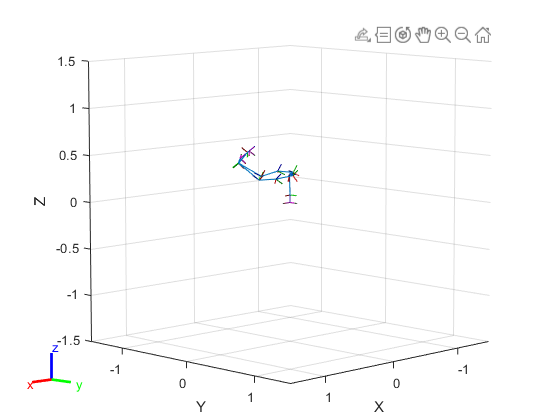

figure(2);
sawyer.show(configuration_sawyer_optimized);

hold on;
show(sawyer, configsawyer);
hold off;